# Minimum Actuation Time - TASK 1/3

### Robot characteristic

%Definizione delle caratteristiche del robot
clc 
clear all
close all
set(0, 'DefaultFigureRenderer', 'painters');
load_robot_specs

P1 = [-0.5 0.75 h-0.2]; % Home position
P2 = [-0.25 1.1 h-0.1];
P3 = [-0.25 1.1 h-0.7];

### 1) Trajectory Planning

dS = norm(P3-P1);
% Alfa
[T_alfa,l1_alfa,l3_alfa] = minActuationTime(acc_limits(1,1),acc_limits(1,2),vel_limits(1,2),dS);
% Beta
[T_beta,l1_beta,l3_beta] = minActuationTime(acc_limits(1,3),acc_limits(1,4),vel_limits(1,4),dS);
% Rho
[T_rho,l1_rho,l3_rho] = minActuationTime(acc_limits(1,5),acc_limits(1,6),vel_limits(1,6),dS);

switch max([T_alfa T_beta T_rho])
    case T_alfa
        T=T_alfa; lamda1=l1_alfa; lamda3=l3_alfa;
    case T_beta
        T=T_beta; lamda1=l1_beta; lamda3=l3_beta;
    case T_rho
        T=T_rho;  lamda1=l1_rho;  lamda3=l3_rho;
end

n = 100;
dT = T/(n-1);

### 1) Kinematics - gripper coordinates 

#### 
$$\dot{Q} = J\dot{S}$$


Calculate the trajectory


$$\dot{J}_s \dot{S} + J_s \ddot{S} + \dot{J} _q \dot{Q}+J_q\ddot{Q}=0$$


Q_1 = inverse_kinematics(P3,L,[130*pi/180 50*pi/180]);
Q_2 = inverse_kinematics(P1,L,[130*pi/180 50*pi/180]);

dQ = Q_2 - Q_1;

for i = 1:n
    t = (i-1)*dT;
    tt(i) = t;
    [q(i,:) qp(i,:) qpp(i,:)] = tretratti(t,T,Q_1,dQ,lamda1,lamda3);
    
    if i==1
        guess = [0 80];
    else
        guess = s(i-1,:);
    end
    
    s(i,:) = direct_kinematics(q(i,:),L,guess);
    [J, J_s, J_q] = Jacobian(s(i,1:2),q(i,1:2),L);
    v(i,:) = inv(J)*qp(i,1:2)';
    a(i,:) = -inv(J_s)*(Jp_s(q(i,1:2),qp(i,1:2),v(i,:),L)*v(i,:)'+Jp_q(s(i,:),q(i,1:2),qp(i,1:2),v(i,:),L)*qp(i,1:2)'+J_q*qpp(i,1:2)');
    
end


### 2D Plot

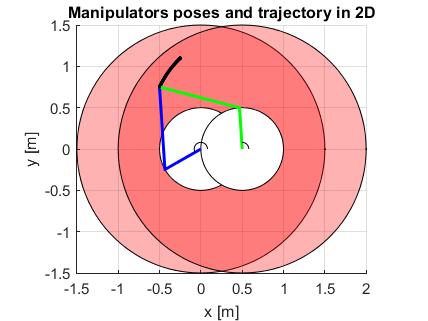

close all

figure(1)
% Plot workspace
center_x = 0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius*cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)
center_x = l0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)

center_x = 0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')

center_x = l0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')
axis equal
grid on

for i=1:length(s)
    % Print
    [config1, theta(i)] = plot2D_1st(q(i,:),L,1,s(i,1),s(i,2));
    [config2, gamma(i)] = plot2D_2nd(q(i,:),L,1,s(i,1),s(i,2));
    plot(s(i,1),s(i,2),'.-black')
    xlim([-1.5 2])
    ylim([-1.5 1.5])
    % Plot the angle arc
    h1 = plotAngleArc([0,0],0.08,[0,q(i,1)],'k-',1); %alfa
    h2 = plotAngleArc([l0,0],0.08,[0,q(i,2)],'k-',1); %beta
    
    pause(dT)
    if i==length(s)
        break
    end
    hold off
    title('Manipulators poses and trajectory in 2D');
    xlabel('x [m]')
    ylabel('y [m]')
    delete(config1); delete(config2); delete(h1); delete(h2);
    
end

### 3D Plot

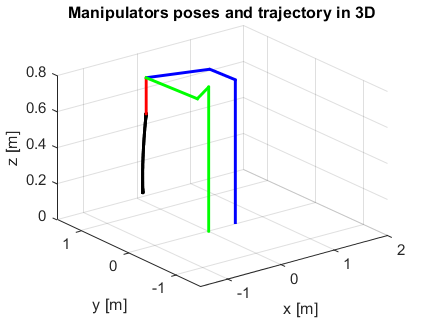

close all
figure(2)
plot3(0,0,0,'LineWidth',4,'color','red') 
xlim([-l1-l2,l0+l1+l2]);
ylim([-l1-l2,l1+l2]);
zlim([0,h]);
xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
title('Manipulators poses and trajectory in 3D');
grid on
for i=1:length(s)
    % Print
    [config1, theta(i)] = Plot3D_1st(q(i,:),L,2,s(i,1),s(i,2));
    [config2, gamma(i)] = Plot3D_2nd(q(i,:),L,2,s(i,1),s(i,2));
    config3 = Plot3D_3rd(L,2,s(i,1),s(i,2),s(i,3));
    plot3(s(i,1),s(i,2),s(i,3),'.-black');
    
    pause(dT)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(config3)
end
hold off

### 1a) Print $\alpha ,\beta ,\gamma \;$and $\theta$

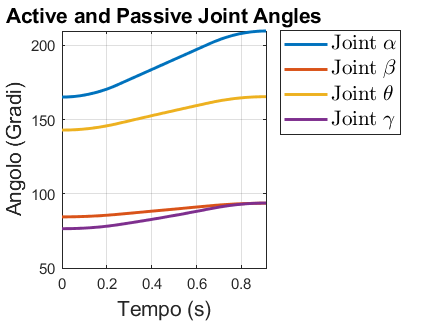

figure(3)
% alpha e beta
plot(tt,q(:,1)*180/pi,'LineWidth',2); hold on
plot(tt,q(:,2)*180/pi,'LineWidth',2); hold on
plot(tt,gamma*180/pi,'LineWidth',2);hold on
plot(tt,theta*180/pi,'LineWidth',2); hold off
xlim([0,tt(end)]);
title('Active and Passive Joint Angles',FontSize=14);
xlabel('Tempo (s)',FontSize=14);
ylabel('Angolo (Gradi)',FontSize=14);
grid on
h_legend=legend('Joint $\alpha$','Joint $\beta$','Joint $\theta$','Joint $\gamma$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);

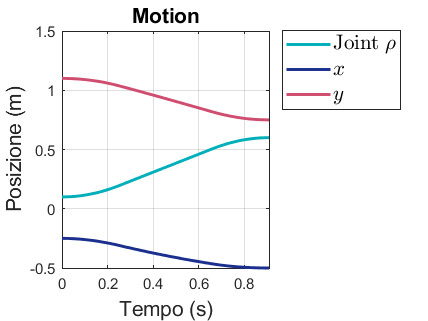



% rho
figure(4)
plot(tt,q(:,3),'Color',[0, 0.6863, 0.7255],'LineWidth',2); hold on
plot(tt,s(:,1),'Color',[0.1 0.1840 0.5560],'LineWidth',2); hold on
plot(tt,s(:,2),'Color',[0.8118, 0.3020, 0.4353],'LineWidth',2); hold off
xlim([0,tt(end)]);
title('Motion',FontSize=14);
xlabel('Tempo (s)',FontSize=14);
ylabel('Posizione (m)',FontSize=14);
grid on
h_legend=legend('Joint $\rho$','$x$','$y$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);

### 1b) Debug

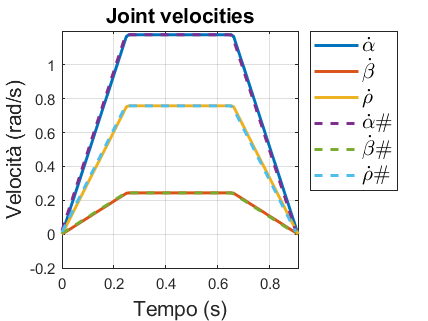

figure(5)
qp_alfa_debug = diff(q(:,1))/dT;
qp_beta_debug = diff(q(:,2))/dT;
qp_rho_debug = diff(q(:,3))/dT;
qpp_alfa_debug = diff(qp(:,1))/dT;
qpp_beta_debug = diff(qp(:,2))/dT;
qpp_rho_debug = diff(qp(:,3))/dT;

figure(6)
plot(tt,qp(:,1),LineWidth=2); hold on
plot(tt,qp(:,2),LineWidth=2); hold on
plot(tt,qp(:,3),LineWidth=2); hold on
plot(tt(1:end-1),qp_alfa_debug,"--",LineWidth=2); hold on
plot(tt(1:end-1),qp_beta_debug,"--",LineWidth=2); hold on
plot(tt(1:end-1),qp_rho_debug,"--",LineWidth=2);
xlim([0,tt(end)]);
h_legend=legend('$\dot{\alpha}$','$\dot{\beta}$','$\dot{\rho}$','$\dot{\alpha}\#$','$\dot{\beta}\#$','$\dot{\rho}\#$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Joint velocities',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Velocità (rad/s)',FontSize=14)
grid on

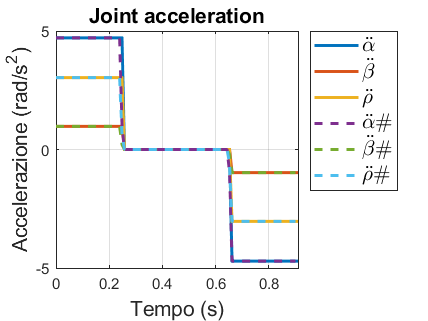


figure(7)
plot(tt,qpp(:,1),LineWidth=2); hold on
plot(tt,qpp(:,2),LineWidth=2); hold on
plot(tt,qpp(:,3),LineWidth=2); hold on
plot(tt(1:end-1),qpp_alfa_debug, "--",LineWidth=2); hold on
plot(tt(1:end-1),qpp_beta_debug,"--",LineWidth=2);
plot(tt(1:end-1),qpp_rho_debug,"--",LineWidth=2);
xlim([0,tt(end)]);
h_legend=legend('$\ddot{\alpha}$','$\ddot{\beta}$','$\ddot{\rho}$','$\ddot{\alpha}\#$','$\ddot{\beta}\#$','$\ddot{\rho}$\#');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Joint acceleration',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Accelerazione (rad/s^2)',FontSize=14)
grid on

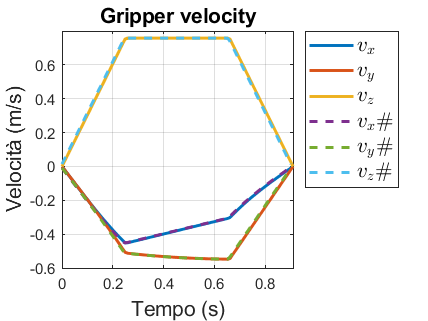


v_x_debug = diff(s(:,1))/dT;
v_y_debug = diff(s(:,2))/dT;
v_z_debug = diff(q(:,3))/dT;
a_x_debug = diff(v(:,1))/dT;
a_y_debug = diff(v(:,2))/dT;
a_z_debug = diff(qp(:,3))/dT;

figure(8)
plot(tt,v(:,1),LineWidth=2); hold on
plot(tt,v(:,2),LineWidth=2); hold on
plot(tt,qp(:,3),LineWidth=2); hold on
plot(tt(1:end-1),v_x_debug, "--",LineWidth=2); hold on
plot(tt(1:end-1),v_y_debug, "--",LineWidth=2); hold on
plot(tt(1:end-1),v_z_debug, "--",LineWidth=2);
xlim([0,tt(end)]);
h_legend=legend('$v_x$','$v_y$','$v_z$','$v_x$\#','$v_y$\#','$v_z$\#');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title("Gripper velocity",FontSize=14)
xlabel('Tempo (s)',FontSize=14)
ylabel('Velocità (m/s)',FontSize=14)
grid on

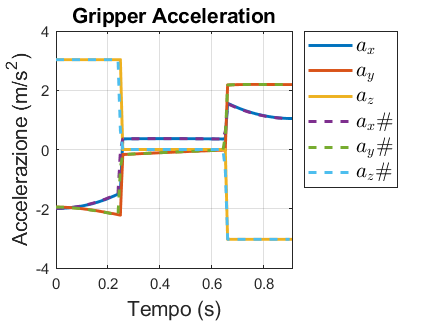


figure(9)
plot(tt,a(:,1),LineWidth=2); hold on
plot(tt,a(:,2) ,LineWidth=2); hold on
plot(tt,qpp(:,3) ,LineWidth=2); hold on
plot(tt(1:end-1),a_x_debug , "--",LineWidth=2); hold on
plot(tt(1:end-1),a_y_debug , "--",LineWidth=2); hold on
plot(tt(1:end-1),a_z_debug, "--",LineWidth=2); 
xlim([0,tt(end)]);
h_legend=legend('$a_x$','$a_y$','$a_z$','$a_x$\#','$a_y$\#','$a_z$\#');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Gripper Acceleration',FontSize=14)
xlabel('Tempo (s)',FontSize=14)
ylabel('Accelerazione (m/s^2)',FontSize=14)
grid on

### 2) Dynamics


$$F_q = ({J_e}^t M J_e)\ddot{Q}+{J_e}^tM\dot{J_e}\dot{Q}-{J_e}^tF_{se}$$


Je_0 = Jacobian_Ext(q(1,1:2),L,G,J);
for i = 2:n
    if i==2
        Je=Jacobian_Ext(q(i,1:2),L,G,J);
        Jep = (Je-Je_0)./dT;
    else
        Je_0=Jacobian_Ext(q(i-1,1:2),L,G,J);
        Je=Jacobian_Ext(q(i,1:2),L,G,J);
        Jep = (Je-Je_0)./dT;
    end
    
    Fq(i,:) = (Je'*M*Je)*qpp(i,1:2)' + (Je'*M*Jep)*qp(i,1:2)'-transpose(Je)*Fse;
    Se=direct_dynamics(q(i,1:2),s(i,:),L,G);
    Sep(:,i) = Je*qp(i,1:2)';
    Ek(i,:) = (1/2)*Sep(:,i)'*M*Sep(:,i);
    Ep(i,:) = transpose(Ag)*M*Se;
    E_tot(i,:) = Ep(i,:) + Ek(i,:);
    W(i,:)=qp(i,1:2)*Fq(i,:)'+Sep(:,i)'*Fse;
end

for i=1:length(qpp)
    Fq(:,3) = m_gripper*(-9.81+qpp(i,3));
end

### 2a) Actuator torques

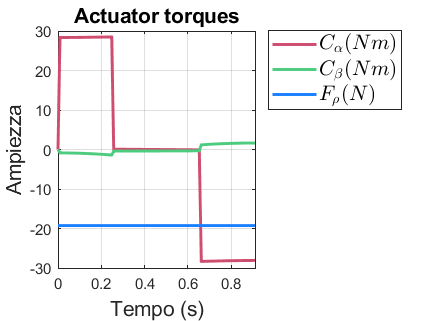

figure(11)
plot(tt,Fq(:,1),'Color',[0.8118, 0.3020, 0.4353],'LineWidth',2); hold on
plot(tt,Fq(:,2),'Color',[0.3, 0.8, 0.5],'LineWidth',2); hold on
plot(tt,Fq(:,3),'Color',[0.1, 0.5, 1],'LineWidth',2);
title("Actuator torques",FontSize=14)
grid on
ylabel('Ampiezza',FontSize=14)
xlabel('Tempo (s)',FontSize=14)
xlim([0,tt(end)])
h_legend = legend('$C_{\alpha} (Nm)$','$C_{\beta}(Nm)$','$F_{\rho} (N)$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);

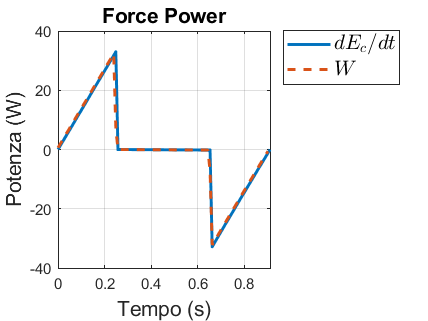


figure(12)
W_debug = diff(E_tot)/dT;
plot(tt,W,LineWidth=2);hold on
plot(tt(1:end-1),W_debug,"--",LineWidth=2);hold off
title("Force Power",FontSize=14)
ylabel('Potenza (W)',FontSize=14)
xlabel('Tempo (s)',FontSize=14)
xlim([0,tt(end)])
h_legend=legend('$dE_c/dt$', '$W$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
grid on

### Checking velocity and acceleration limits

% Velocity
for i=1:length(qp)
    if (qp(i,1) < vel_limits(1)) && (qp(i,1)>vel_limits(2))
        msgbox('Actuator limit exceeded on alpha')
    end
    if (qp(i,2) < vel_limits(3)) && (qp(i,2)>vel_limits(4))
        msgbox('Actuator limit exceeded on beta')
    end
    if (qp(i,3) < vel_limits(5)) && (qp(i,3)>vel_limits(6))
        msgbox('Actuator limit exceeded on rho')
    end
end

% Acceleration
for i=1:length(qpp)
    if (qpp(i,1) < -acc_limits(1)) && (qpp(i,1)>acc_limits(2))
        msgbox('Actuator limit exceeded on alpha')
    end
    if (qpp(i,2) < -acc_limits(3)) && (qpp(i,2)>acc_limits(4))
        msgbox('Actuator limit exceeded on beta')
    end
    if (qpp(i,3) < -acc_limits(5)) && (qpp(i,3)>acc_limits(6))
        msgbox('Actuator limit exceeded on rho')
    end
end